Initialize variables for importing data

clc; clear all;
subject_num = 9006;
dof_type    = "drinking_task";
filepath = "C:/Git/FES_Exo/data/data_collection/S" + subject_num + "/" + dof_type + "/";

fileset1 = []

fileset2 = []

% files = dir(filepath);
% files = files(3:end); % remove '.' and '..'

start_time = 0.0; % time when movement starts that we want to look at

% warning('OFF', 'MATLAB:table:ModifiedAndSavedVarnames') % supress warning for variable names
for i = 1:length(fileset1)
    T1{i} = readtable(filepath + fileset1);
    T1{i} = T1{i}(find(T1{i}.time_s_>=start_time,1):end,:);
    T1{i}.time_s_ = T1{i}.time_s_ - T1{i}.time_s_(1);
end

for i = 1:length(fileset2)
    T2{i} = readtable(filepath + fileset2);
    T2{i} = T2{i}(find(T2{i}.time_s_>=start_time,1):end,:);
    T2{i}.time_s_ = T2{i}.time_s_ - T2{i}.time_s_(1);
end

Combing through data to quantify features of data. Data collected here is:

- RMS Torque

- Max Torque

- RMS Error

for i = 1:length(T1)
    fes_share1(i)       = T1{i}.kp_val__(1);
    
    elbow_rms_torque1(i)    = rms(T1{i}.elbow_fe_trq_Nm_);
    forearm_rms_torque1(i)  = rms(T1{i}.forearm_ps_trq_Nm_);
    wrist_fe_rms_torque1(i) = rms(T1{i}.wrist_fe_trq_Nm_);
    wrist_ru_rms_torque1(i) = rms(T1{i}.wrist_ru_trq_Nm_);
    
    elbow_max_torque1(i)    = max(abs(T1{i}.elbow_fe_trq_Nm_));
    forearm_max_torque1(i)  = max(abs(T1{i}.forearm_ps_trq_Nm_));
    wrist_fe_max_torque1(i) = max(abs(T1{i}.wrist_fe_trq_Nm_));
    wrist_ru_max_torque1(i) = max(abs(T1{i}.wrist_ru_trq_Nm_));
    
    elbow_rms_error1(i)    = rms(T1{i}.com_elbow_fe_rad_   - T1{i}.act_elbow_fe_rad_);
    forearm_rms_error1(i)  = rms(T1{i}.com_forearm_ps_rad_ - T1{i}.act_forearm_ps_rad_);
    wrist_fe_rms_error1(i) = rms(T1{i}.com_wrist_fe_rad_   - T1{i}.act_wrist_fe_rad_);
    wrist_ru_rms_error1(i) = rms(T1{i}.com_wrist_ru_rad_   - T1{i}.act_wrist_ru_rad_);
end

for i = 1:length(T2)
    fes_share2(i)       = T2{i}.kp_val__(1);
    
    elbow_rms_torque2(i)    = rms(T2{i}.elbow_fe_trq_Nm_);
    forearm_rms_torque2(i)  = rms(T2{i}.forearm_ps_trq_Nm_);
    wrist_fe_rms_torque2(i) = rms(T2{i}.wrist_fe_trq_Nm_);
    wrist_ru_rms_torque2(i) = rms(T2{i}.wrist_ru_trq_Nm_);
    
    elbow_max_torque2(i)    = max(abs(T2{i}.elbow_fe_trq_Nm_));
    forearm_max_torque2(i)  = max(abs(T2{i}.forearm_ps_trq_Nm_));
    wrist_fe_max_torque2(i) = max(abs(T2{i}.wrist_fe_trq_Nm_));
    wrist_ru_max_torque2(i) = max(abs(T2{i}.wrist_ru_trq_Nm_));
    
    elbow_rms_error2(i)    = rms(T2{i}.com_elbow_fe_rad_   - T2{i}.act_elbow_fe_rad_);
    forearm_rms_error2(i)  = rms(T2{i}.com_forearm_ps_rad_ - T2{i}.act_forearm_ps_rad_);
    wrist_fe_rms_error2(i) = rms(T2{i}.com_wrist_fe_rad_   - T2{i}.act_wrist_fe_rad_);
    wrist_ru_rms_error2(i) = rms(T2{i}.com_wrist_ru_rad_   - T2{i}.act_wrist_ru_rad_);
end

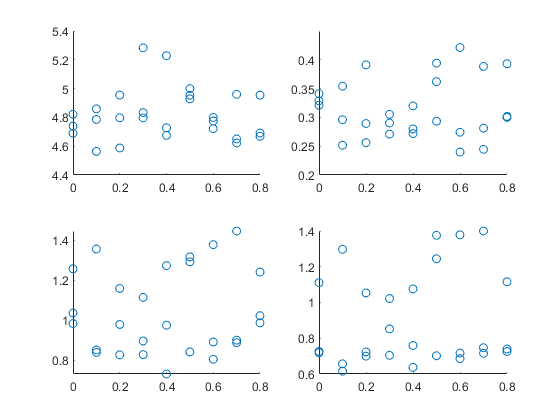


figure()
% Elbow
subplot(1,3,1)
data = []
bar

% Forearm
subplot(1,3,2)
scatter(fes_share,forearm_max_torque)

% Wrist FE
subplot(1,3,3)
scatter(fes_share,wrist_fe_max_torque)

% Wrist RU
subplot(2,2,4)
scatter(fes_share,wrist_ru_max_torque)

Formatting data so that it can be used for proper plotting including getting mean and std for the following features.

- RMS Torque

- Max Torque

- RMS Error

fes_amts_possible = 0:0.05:1.0;

i = 0;
for fes_amt = fes_amts_possible
    
    indices = abs(fes_share - fes_amt) < 0.001;
    
    if sum(indices) > 0
        i = i + 1;
        
        fes_amts(i) = fes_amt;
        
        % RMS TORQUE
        elbow_rms_torque_local    = elbow_rms_torque(indices);
        forearm_rms_torque_local  = forearm_rms_torque(indices);
        wrist_fe_rms_torque_local = wrist_fe_rms_torque(indices);
        wrist_ru_rms_torque_local = wrist_ru_rms_torque(indices);
        
        elbow_rms_torque_std(i)     = std(elbow_rms_torque_local);
        elbow_rms_torque_mean(i)    = mean(elbow_rms_torque_local);
        forearm_rms_torque_std(i)   = std(forearm_rms_torque_local);
        forearm_rms_torque_mean(i)  = mean(forearm_rms_torque_local);
        wrist_fe_rms_torque_std(i)  = std(wrist_fe_rms_torque_local);
        wrist_fe_rms_torque_mean(i) = mean(wrist_fe_rms_torque_local);
        wrist_ru_rms_torque_std(i)  = std(wrist_ru_rms_torque_local);
        wrist_ru_rms_torque_mean(i) = mean(wrist_ru_rms_torque_local);
        
        % MAX TORQUE
        elbow_max_torque_local    = elbow_max_torque(indices);
        forearm_max_torque_local  = forearm_max_torque(indices);
        wrist_fe_max_torque_local = wrist_fe_max_torque(indices);
        wrist_ru_max_torque_local = wrist_ru_max_torque(indices);
        
        elbow_max_torque_std(i)     = std(elbow_max_torque_local);
        elbow_max_torque_mean(i)    = mean(elbow_max_torque_local);
        forearm_max_torque_std(i)   = std(forearm_max_torque_local);
        forearm_max_torque_mean(i)  = mean(forearm_max_torque_local);
        wrist_fe_max_torque_std(i)  = std(wrist_fe_max_torque_local);
        wrist_fe_max_torque_mean(i) = mean(wrist_fe_max_torque_local);
        wrist_ru_max_torque_std(i)  = std(wrist_ru_max_torque_local);
        wrist_ru_max_torque_mean(i) = mean(wrist_ru_max_torque_local);
        
        % RMS ERROR
        elbow_rms_error_local    = elbow_rms_error(indices);
        forearm_rms_error_local  = forearm_rms_error(indices);
        wrist_fe_rms_error_local = wrist_fe_rms_error(indices);
        wrist_ru_rms_error_local = wrist_ru_rms_error(indices);
        
        elbow_rms_error_std(i)     = std(elbow_rms_error_local);
        elbow_rms_error_mean(i)    = mean(elbow_rms_error_local);
        forearm_rms_error_std(i)   = std(forearm_rms_error_local);
        forearm_rms_error_mean(i)  = mean(forearm_rms_error_local);
        wrist_fe_rms_error_std(i)  = std(wrist_fe_rms_error_local);
        wrist_fe_rms_error_mean(i) = mean(wrist_fe_rms_error_local);
        wrist_ru_rms_error_std(i)  = std(wrist_ru_rms_error_local);
        wrist_ru_rms_error_mean(i) = mean(wrist_ru_rms_error_local);
        
        stats{i}.fes_amt = fes_amt;
        
        stats{i}.elbow_rms_torque    = elbow_rms_torque_local;
        stats{i}.forearm_rms_torque  = forearm_rms_torque_local;
        stats{i}.wrist_fe_rms_torque = wrist_fe_rms_torque_local;
        stats{i}.wrist_ru_rms_torque = wrist_ru_rms_torque_local;
        
        stats{i}.elbow_max_torque    = elbow_max_torque_local;
        stats{i}.forearm_max_torque  = forearm_max_torque_local;
        stats{i}.wrist_fe_max_torque = wrist_fe_max_torque_local;
        stats{i}.wrist_ru_max_torque = wrist_ru_max_torque_local;
        
        stats{i}.elbow_rms_error    = elbow_rms_error_local;
        stats{i}.forearm_rms_error  = forearm_rms_error_local;
        stats{i}.wrist_fe_rms_error = wrist_fe_rms_error_local;
        stats{i}.wrist_ru_rms_error = wrist_ru_rms_error_local;
    end
end

fes_percent = fes_amts;


All plotting for paper

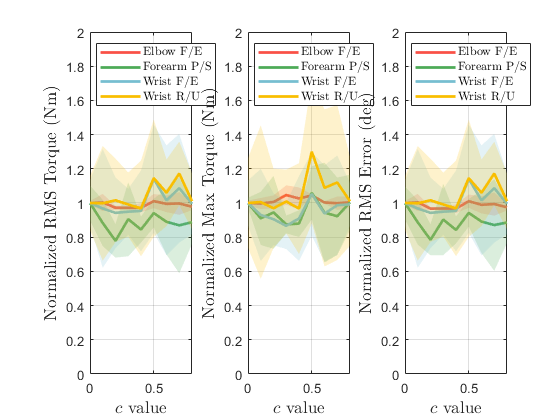

single_plot = true;
normalize   = true;

h = figure();
% Plotting for RMS Torque
% figure()
subplot(1,3,1)
titles = ["Elbow F/E", "Forearm P/S", "Wrist F/E", "Wrist R/U"];
means  = [elbow_rms_torque_mean;  forearm_rms_torque_mean; wrist_fe_rms_torque_mean; wrist_ru_rms_torque_mean];
stds   = [ elbow_rms_torque_std;   forearm_rms_torque_std;  wrist_fe_rms_torque_std;  wrist_ru_rms_torque_std];
PlotPaper(titles, fes_percent, means, stds, "$c$ value", "RMS Torque (Nm)", normalize, single_plot);
% title('')

% Plotting for Max Torque
% figure()
subplot(1,3,2)
titles = ["Elbow F/E", "Forearm P/S", "Wrist F/E", "Wrist R/U"];
means  = [elbow_max_torque_mean;  forearm_max_torque_mean; wrist_fe_max_torque_mean; wrist_ru_max_torque_mean];
stds   = [ elbow_max_torque_std;   forearm_max_torque_std;  wrist_fe_max_torque_std; wrist_ru_max_torque_std];
PlotPaper(titles, fes_percent, means, stds, "$c$ value", "Max Torque (Nm)", normalize, single_plot);
% title('')

% Plotting for RMS Error
% figure()
subplot(1,3,3)
titles = ["Elbow F/E", "Forearm P/S", "Wrist F/E", "Wrist R/U"];
means  = [elbow_rms_error_mean;  forearm_rms_error_mean; wrist_fe_rms_error_mean; wrist_ru_rms_error_mean];
stds   = [ elbow_rms_error_std;   forearm_rms_error_std;  wrist_fe_rms_error_std;  wrist_ru_rms_error_std];
PlotPaper(titles, fes_percent, rad2deg(means), rad2deg(stds), "$c$ value", "RMS Error (deg)", normalize, single_plot);

% % title('')

% set(h,'Position',[100,100,1000,250],'Units','Inches');
% pos = get(h,'Position');
% set(h,'PaperPositionMode','Auto','PaperUnits','Inches','PaperSize',[pos(3)-1.7, pos(4)+0.25])
% print(h,dof_type+"DofResults.pdf",'-dpdf','-r0')

RMS torque plotting

figure()

titles = ["Elbow F/E", "Forearm P/S", "Wrist F/E", "Wrist R/U"];
means  = [elbow_rms_torque_mean;  forearm_rms_torque_mean; wrist_fe_rms_torque_mean; wrist_ru_rms_torque_mean];
stds   = [ elbow_rms_torque_std;   forearm_rms_torque_std;  wrist_fe_rms_torque_std; wrist_ru_rms_torque_std];

for i = 1:4
    subplot(2,2,i)
    errorbar(fes_percent,means(i,:),2*stds(i,:))
    title(titles(i))
    xlabel("c value")
    ylabel("RMS Torque (Nm)")
    grid on
end

Max torque plotting

figure()

titles = ["Elbow F/E", "Forearm P/S", "Wrist F/E", "Wrist R/U"];
means  = [elbow_max_torque_mean;  forearm_max_torque_mean; wrist_fe_max_torque_mean; wrist_ru_max_torque_mean];
stds   = [ elbow_max_torque_std;   forearm_max_torque_std;  wrist_fe_max_torque_std; wrist_ru_max_torque_std];

for i = 1:4
    subplot(2,2,i)
    errorbar(fes_percent,means(i,:),2*stds(i,:))
    title(titles(i))
    xlabel("c value")
    ylabel("Max Torque (Nm)")
    grid on
end

RMS Error plotting

figure()

titles = ["Elbow F/E", "Forearm P/S", "Wrist F/E", "Wrist R/U"];
means  = [elbow_rms_error_mean;  forearm_rms_error_mean; wrist_fe_rms_error_mean; wrist_ru_rms_error_mean];
stds   = [ elbow_rms_error_std;   forearm_rms_error_std;  wrist_fe_rms_error_std;  wrist_ru_rms_error_std];

for i = 1:4
    subplot(2,2,i)
    errorbar(fes_percent,rad2deg(means(i,:)),2*rad2deg(stds(i,:)))
    title(titles(i))
    xlabel("c value")
    ylabel("RMS error (deg)")
    grid on
end


Export data to run in R

variable_names = ["fes_share",...
                  "elbow_rms_torque", "forearm_rms_torque", "wrist_fe_rms_torque", "wrist_ru_rms_torque",...
                  "elbow_max_torque", "forearm_max_torque", "wrist_fe_max_torque", "wrist_ru_max_torque",...
                  "elbow_rms_error",  "forearm_rms_error",  "wrist_fe_rms_error",  "wrist_ru_rms_error"];

output_data = [fes_share',...
               elbow_rms_torque', forearm_rms_torque', wrist_fe_rms_torque', wrist_ru_rms_torque',...
               elbow_max_torque', forearm_max_torque', wrist_fe_max_torque', wrist_ru_max_torque',...
                elbow_rms_error',  forearm_rms_error',  wrist_fe_rms_error',  wrist_ru_rms_error']
            
output_table = array2table(output_data);
output_table.Properties.VariableNames = variable_names;

if dof_type == "single"
    output_table(17,:) = [];
end
writetable(output_table,dof_type + "_stats.csv")

Running T-Tests for data

for i = 1:length(stats)-1
    [   test_results.elbow_rms_torque_h(i),   test_results.elbow_rms_torque(i)] = ttest2(   stats{1}.elbow_rms_torque,   stats{i+1}.elbow_rms_torque,'Vartype',"unequal");
    [ test_results.forearm_rms_torque_h(i), test_results.forearm_rms_torque(i)] = ttest2( stats{1}.forearm_rms_torque, stats{i+1}.forearm_rms_torque,'Vartype',"unequal");
    [test_results.wrist_fe_rms_torque_h(i),test_results.wrist_fe_rms_torque(i)] = ttest2(stats{1}.wrist_fe_rms_torque,stats{i+1}.wrist_fe_rms_torque,'Vartype',"unequal");
    [test_results.wrist_ru_rms_torque_h(i),test_results.wrist_ru_rms_torque(i)] = ttest2(stats{1}.wrist_ru_rms_torque,stats{i+1}.wrist_ru_rms_torque,'Vartype',"unequal");
    
    [   test_results.elbow_max_torque_h(i),   test_results.elbow_max_torque(i)] = ttest2(   stats{1}.elbow_max_torque,   stats{i+1}.elbow_max_torque,'Vartype',"unequal");
    [ test_results.forearm_max_torque_h(i), test_results.forearm_max_torque(i)] = ttest2( stats{1}.forearm_max_torque, stats{i+1}.forearm_max_torque,'Vartype',"unequal");
    [test_results.wrist_fe_max_torque_h(i),test_results.wrist_fe_max_torque(i)] = ttest2(stats{1}.wrist_fe_max_torque,stats{i+1}.wrist_fe_max_torque,'Vartype',"unequal");
    [test_results.wrist_ru_max_torque_h(i),test_results.wrist_ru_max_torque(i)] = ttest2(stats{1}.wrist_ru_max_torque,stats{i+1}.wrist_ru_max_torque,'Vartype',"unequal");

    [   test_results.elbow_rms_error_h(i),   test_results.elbow_rms_error(i)] = ttest2(   stats{1}.elbow_rms_error,   stats{i+1}.elbow_rms_error,'Vartype',"unequal");
    [ test_results.forearm_rms_error_h(i), test_results.forearm_rms_error(i)] = ttest2( stats{1}.forearm_rms_error, stats{i+1}.forearm_rms_error,'Vartype',"unequal");
    [test_results.wrist_fe_rms_error_h(i),test_results.wrist_fe_rms_error(i)] = ttest2(stats{1}.wrist_fe_rms_error,stats{i+1}.wrist_fe_rms_error,'Vartype',"unequal");
    [test_results.wrist_ru_rms_error_h(i),test_results.wrist_ru_rms_error(i)] = ttest2(stats{1}.wrist_ru_rms_error,stats{i+1}.wrist_ru_rms_error,'Vartype',"unequal");
end


trying nonparametric instead

for i = 1:length(stats)-1
    [   test_results.elbow_rms_torque_h(i),   test_results.elbow_rms_torque(i)] = ranksum(   stats{1}.elbow_rms_torque,   stats{i+1}.elbow_rms_torque);
    [ test_results.forearm_rms_torque_h(i), test_results.forearm_rms_torque(i)] = ranksum( stats{1}.forearm_rms_torque, stats{i+1}.forearm_rms_torque);
    [test_results.wrist_fe_rms_torque_h(i),test_results.wrist_fe_rms_torque(i)] = ranksum(stats{1}.wrist_fe_rms_torque,stats{i+1}.wrist_fe_rms_torque);
    [test_results.wrist_ru_rms_torque_h(i),test_results.wrist_ru_rms_torque(i)] = ranksum(stats{1}.wrist_ru_rms_torque,stats{i+1}.wrist_ru_rms_torque);
    
    [   test_results.elbow_max_torque_h(i),   test_results.elbow_max_torque(i)] = ranksum(   stats{1}.elbow_max_torque,   stats{i+1}.elbow_max_torque);
    [ test_results.forearm_max_torque_h(i), test_results.forearm_max_torque(i)] = ranksum( stats{1}.forearm_max_torque, stats{i+1}.forearm_max_torque);
    [test_results.wrist_fe_max_torque_h(i),test_results.wrist_fe_max_torque(i)] = ranksum(stats{1}.wrist_fe_max_torque,stats{i+1}.wrist_fe_max_torque);
    [test_results.wrist_ru_max_torque_h(i),test_results.wrist_ru_max_torque(i)] = ranksum(stats{1}.wrist_ru_max_torque,stats{i+1}.wrist_ru_max_torque);

    [   test_results.elbow_rms_error_h(i),   test_results.elbow_rms_error(i)] = ranksum(   stats{1}.elbow_rms_error,   stats{i+1}.elbow_rms_error);
    [ test_results.forearm_rms_error_h(i), test_results.forearm_rms_error(i)] = ranksum( stats{1}.forearm_rms_error, stats{i+1}.forearm_rms_error);
    [test_results.wrist_fe_rms_error_h(i),test_results.wrist_fe_rms_error(i)] = ranksum(stats{1}.wrist_fe_rms_error,stats{i+1}.wrist_fe_rms_error);
    [test_results.wrist_ru_rms_error_h(i),test_results.wrist_ru_rms_error(i)] = ranksum(stats{1}.wrist_ru_rms_error,stats{i+1}.wrist_ru_rms_error);
end